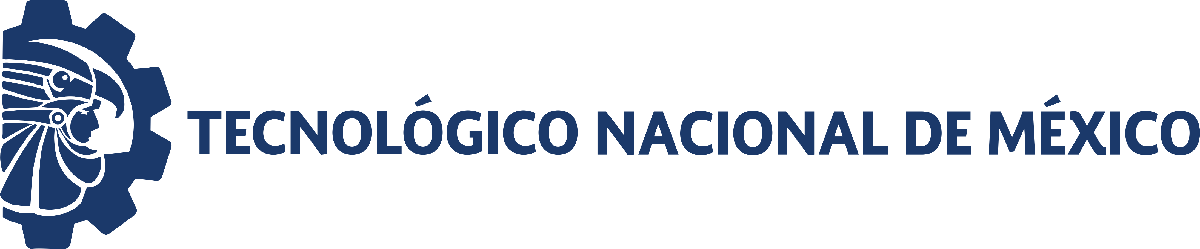                                 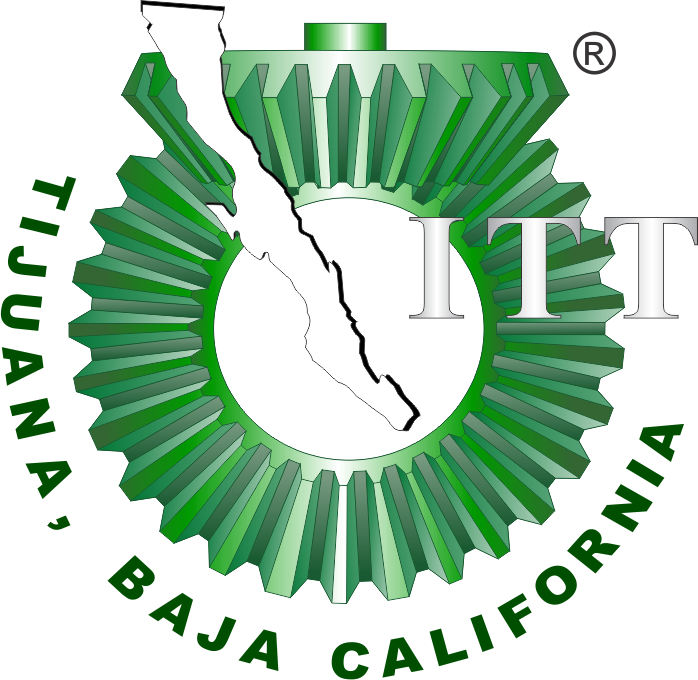

# Práctica uno: Diseño de controlador para un sistema de segundo orden

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

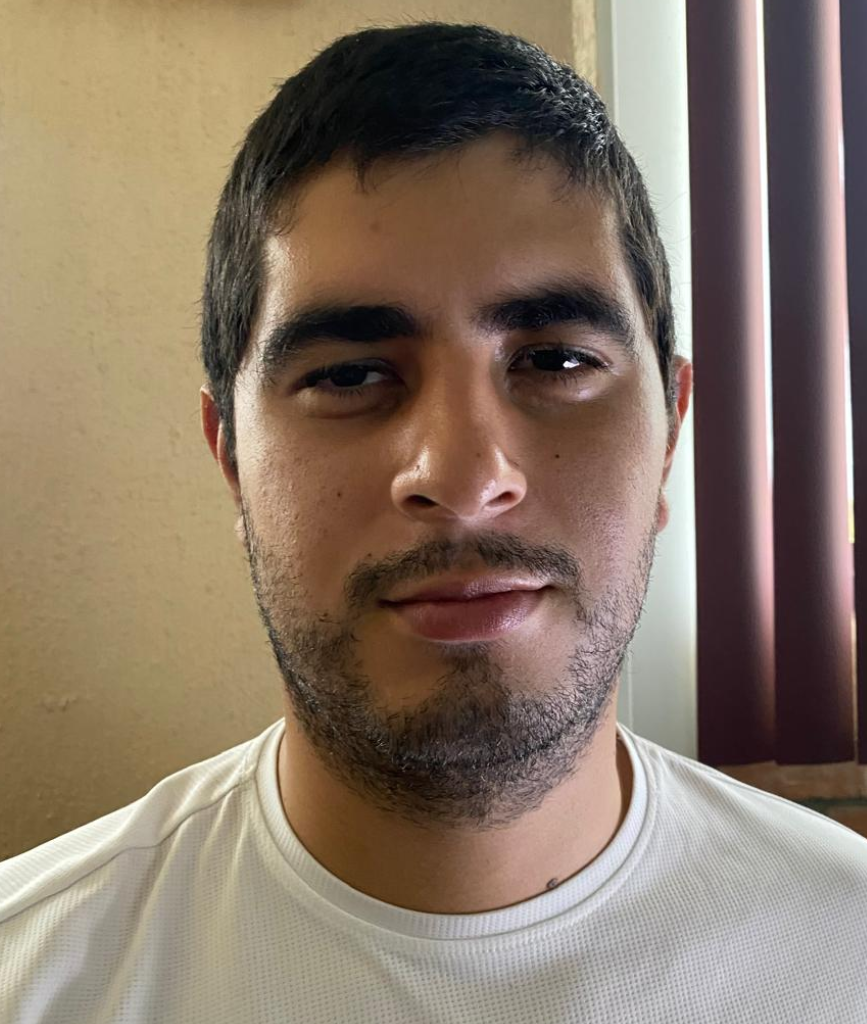

Nombre del alumno: **Edgar Iván Rivas Rosas**

Número de control: **21212748**

Correo institucional:** l21212748@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = "10";
file = "sysp1";
open_system(file);
parameters.StopTime = tend;
parameters.Solver = "ode45";
parameters.MaxStep = "1E-3";
Controlador = "PID";

## Respuesta al escalón

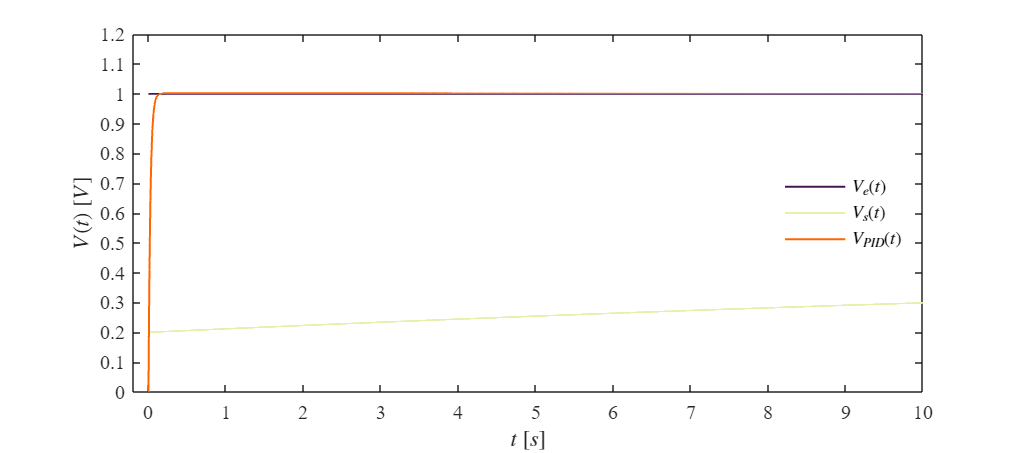

Signal='Escalon';
set_param("sysp1/S1","sw","1");
set_param("sysp1/Ve(t)","sw","1");
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Ve,x1.Vs,x1.VPID,Signal)

## Respuesta al impulso

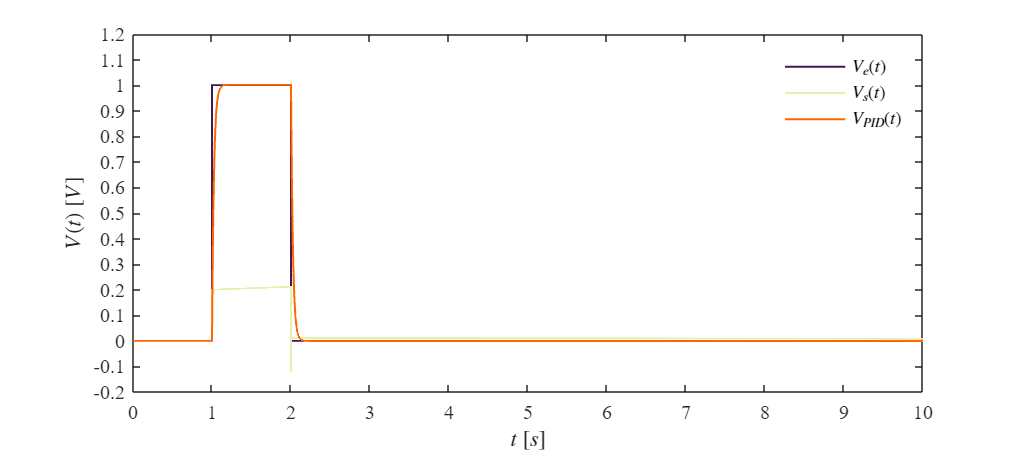

Signal='Impulso';
set_param("sysp1/S1","sw","0");
set_param("sysp1/Ve(t)","sw","1");
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Ve,x2.Vs,x2.VPID,Signal)

## Respuesta a la rampa

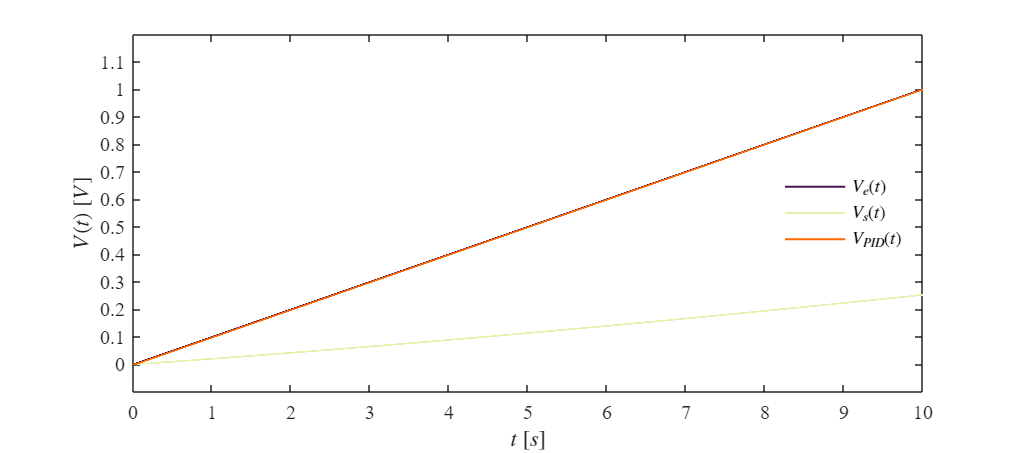

Signal='Rampa';
set_param("sysp1/S2","sw","1");
set_param("sysp1/Ve(t)","sw","0");
x3 = sim(file,parameters);
plotsignals(x3.t,x3.Ve,x3.Vs,x3.VPID,Signal)

## Respuesta a la función sinusoidal

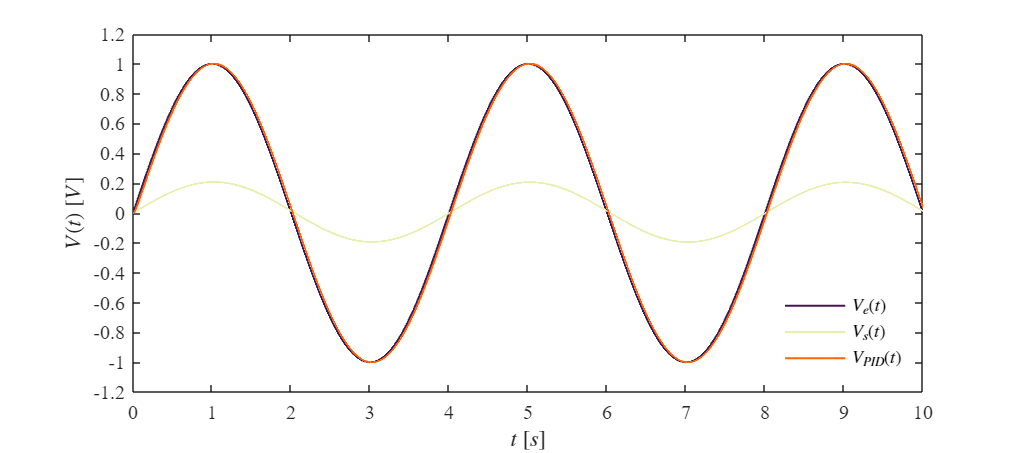

Signal='Sinusoidal';
set_param("sysp1/S2","sw","0");
set_param("sysp1/Ve(t)","sw","0");
x4 = sim(file,parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.VPID,Signal)

## Función: Respuesta a las señales

function plotsignals(t,Ve,Vs,VPID,Signal)
    set(figure(), "Color", "w")
    set(gcf,"units","Centimeters","Position",[1,1,18,8])
    set(gca,"FontName","Times New Roman")
    fontsize(10,"points")
    morado =[68/255, 23/255, 82/255];
    rosa =[255/255, 116/255, 139/255];
    naranja =[255/255, 101/255, 0/255];
    verde = [228/255, 241/255, 172/255];
    hold on; grid off; box on

    plot(t,Ve,"LineWidth",1,"Color",morado)
    plot(t,Vs,"LineWidth",1,"Color",verde)
    plot(t,VPID,"LineWidth",1,"Color",naranja)

    xlabel('$t$ $[s]$', 'Interpreter','Latex')
    ylabel('$V(t)$ $[V]$', 'Interpreter','Latex')

    L = legend("$V_{e}(t)$","$V_{s}(t)$","$V_{PID}(t)$");
    set(L,"Interpreter","Latex","Location",'Best',"Box","Off")

    if Signal == "Escalon"
        xlim([-0.2, 10]); xticks(0:1:10)
        ylim([0,1.2]); yticks(0:0.1:1.2)
    elseif Signal == "Impulso"
        xlim([0, 10]); xticks(0:1:10)
        ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2)
    elseif Signal == "Rampa"
        xlim([0, 10]); xticks(0:1:10)
        ylim([-0.1,1.2]); yticks(0:0.1:1.1)
    elseif Signal == "Sinusoidal"
        xlim([0, 10]); xticks(0:1:10)
        ylim([-1.2,1.2]); yticks(-1.2:0.2:1.2)
    end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end